# Agrupamiento k-means

% clear;
% declaraciones;
% 
% dir_data = "D:\DATA\";
% 
% ae = exist("arr_ndvi","var");
% if ae == 0  %si no existe, cargar la infromación
%     load (dir_data+"info_ndvi_all.mat");
% 
%     num_mediciones = 519;
% end

ae = exist("arr_ndvi","var");
if ae == 0  %si no existe, cargar la infromación
    new_cargar_informacion
end

## Filtrar información

% Declaraciones
% Los años que se desean consultar

anios = 2000:2022;

% Arreglo donde se almacenara el promedio de NDVI por año
indices_series =zeros(total_pixeles,4);

% generar indices 

bp=waitbar(0,'Generando indice de series de tiempo'); 
k=1;
for i=1:ndvi_tam(2)
     for j=1:ndvi_tam(1)
        indices_series(k,1) = k;
        indices_series(k,2) = j;
        indices_series(k,3) = i;
         if sum(~isnan(arr_ndvi_lf(j,i,:)))==0
             indices_series(k,4) = 0;
         else
             indices_series(k,4) = 1;
         end
        k=k+1;
     end
     waitbar(i/ndvi_tam(2),bp,sprintf('Generando indice de series de tiempo (%3.0f%%) ',(i/ndvi_tam(2)*100)));
end
close (bp);



num_mediciones = 519;

series_tiempo_all = reshape(arr_ndvi_lf, ndvi_tam(1)*ndvi_tam(2) , num_mediciones)';

serie_tiempo =  series_tiempo_all(:,indices_series(:,4)==1);
sti = indices_series(indices_series(:,4)==1,1);

## Generar mapa de grupos

num_grupos = 2;

grupos = kmeans(serie_tiempo',num_grupos);

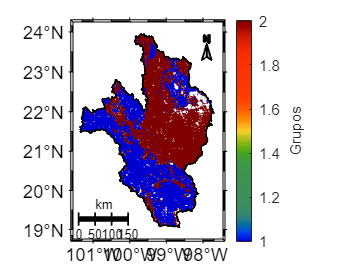


mapa_grupos = NaN(ndvi_tam(1),ndvi_tam(2));

for k=1: length(sti)
    mapa_grupos( indices_series( sti(k),2) ,  indices_series( sti(k),3) )=grupos(k);
end

figure;
mapa_grupos(area_estudio==false)=nan;

m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,mapa_grupos,"",[1 num_grupos],m_colmap('jet','step',num_grupos),"Grupos");
m_dibujar_kml(dir_data,"RH26",1,"k","");

 exportgraphics(gca,"img/k-means_"+num_grupos+".png",'Resolution',300) 

load info_topo.mat

topo = m_cambiar_resolucion(lat,lon,lat_topo,lon_topo,data_topo);


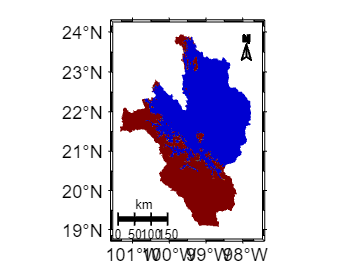

topo(area_estudio==false)=nan;
topo(topo<0)=0;

%m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,topo,"México",[],m_colmap('gland',256),"mts");

umbral = 1700;%mejor correlacion = 1691m; CORR: 0.46845
topo_g = topo;

topo_g(topo>umbral) = 2;
topo_g(topo<=umbral) = 1;

m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,topo_g,"",[1 num_grupos],m_colmap('jet','step',num_grupos),"");

%m_dibujar_kml(dir_data,"RH26",1,"k","");


## Correlacion entre elevavion y promedio de ndvi



B = reshape(topo,[],1);
fb = find(B<-1 | B>210000);
B(fb)=nan;
B = B(~isnan(B));

ndvi_prom = m_mean_3dpp(arr_ndvi_sgf);
C = reshape(ndvi_prom,[],1);
C(fb)=nan;
C = C(~isnan(C));

R = corrcoef(B,C);
disp("Correlación: "+R(2,1));

Correlación: -0.4385


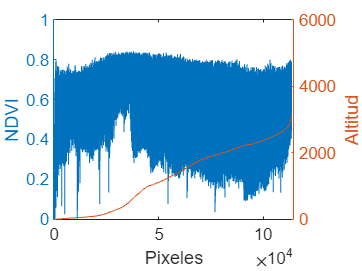


tabla = [B C];
tabla = sortrows(tabla);

ex = 1:length(B);

figure;
yyaxis left 
plot(tabla(:,2));
xlabel('Pixeles')
ylabel('NDVI')
yyaxis right
plot(ex,tabla(:,1));
ylabel('Altitud')

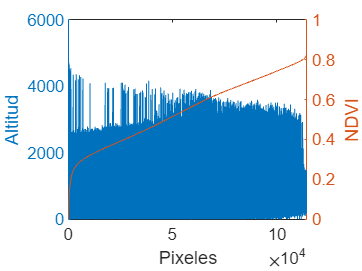


tabla = sortrows(tabla,2);

figure;
yyaxis left 
plot(ex,tabla(:,1));
xlabel('Pixeles')
ylabel('Altitud')
yyaxis right
plot(ex,tabla(:,2));
ylabel('NDVI')

## Cuenta pixeles


% % A = reshape(mapa_grupos,[],1);
% % A = A(~isnan(A));

% % g1 = numel( find(A==1&B==1))
% % g2 = numel( find(A==2&B==2))
% % g1_kmeans = numel( find(B==1))
% % g2_kmeans = numel( find(B==2))
% % 
% % C= zeros(total_pixeles,1);
% % C(A==B)=1;
% % 
% % suma = sum(C)
% % p = suma/total_pixeles


% mapa_diff = NaN(size(mapa_grupos));
% 
% mapa_diff(mapa_grupos==topo_g)=2;
% 
% mapa_diff(area_estudio==false)=nan;
% m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,mapa_diff,"",[1 num_grupos],m_colmap('jet','step',num_grupos),"");
% %m_dibujar_kml(dir_data,"RH26",1,"k","");



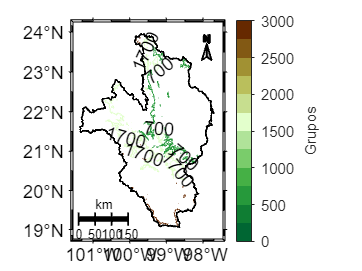


figure;
m_proj('mercator','lon',lon_mapa,'lat',lat_mapa);

colormap(elevation_colormap);   
m_contour(lon,lat,topo,[0 700 1700 3000],'ShowText','on');

m_grid('linestyle','none','box','fancy','tickdir','out');
%m_grid('linewi',2,'tickdir','out');

colorbar('eastoutside');
c = colorbar;
c.Label.String = "Grupos";
c.TickDirection = "out";

% % Regla de escala
m_ruler([.05 .36],.1,3,'fontsize',7)
% %m_northarrow(-101,23.5,.4,'type',2);
% % Estrella del norte 
m_northarrow(-97.9,23.5,.4,'type',2);
m_dibujar_kml(dir_data,"RH26",1,"k","");


 exportgraphics(gca,"img/lineas_elevacion.png",'Resolution',300) 

## Probar con NDVI solo septiembre

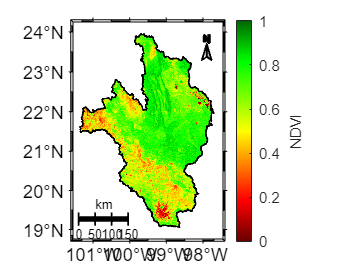

tmp =  find(  info_hdf.mes == 9  ); % Septiembre

arr_ndvi_lf_max = arr_ndvi_lf(:,:,tmp);

prom_ndvi_max = m_mean_3dpp(arr_ndvi_lf_max);

prom_ndvi_max(area_estudio==false)=nan;

m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,prom_ndvi_max,"",[0 1],ndvi_colormap,"NDVI");
m_dibujar_kml(dir_data,"RH26",1,'k',"")

exportgraphics(gca,"img/promedio_ndvi_max(sept)_sgf.png",'Resolution',300) ;


C = reshape(prom_ndvi_max,[],1);
C(fb)=nan;

C = C(~isnan(C));

R = corrcoef(B,C);
disp("Correlación: "+R(2,1));

Correlación: -0.45255


## Buscar correlación agrupando altitudes cada 250m

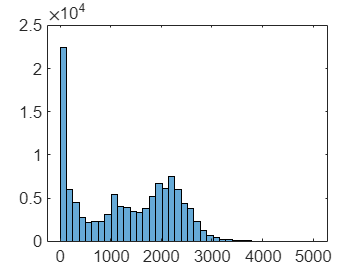

num_bins = 40;

histo_topo = histogram(B,num_bins);

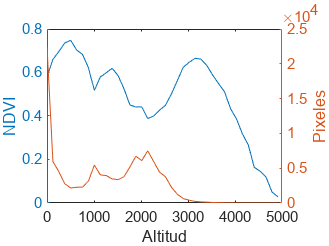

histo_topo_val = histo_topo.Values;

ndvi_lf_g250 = zeros(length(histo_topo_val),1);

be = histo_topo.BinEdges;

for i=1:length(ndvi_lf_g250)
    ndvi_lf_g250(i) = mean( ndvi_prom(  topo >= be(i)  & topo <= be(i+1)) );
end


figure;
yyaxis left 
plot(be(1:num_bins),ndvi_lf_g250);
xlabel('Altitud')
ylabel('NDVI')
yyaxis right
plot(be(1:num_bins),histo_topo_val);
ylabel('Pixeles')